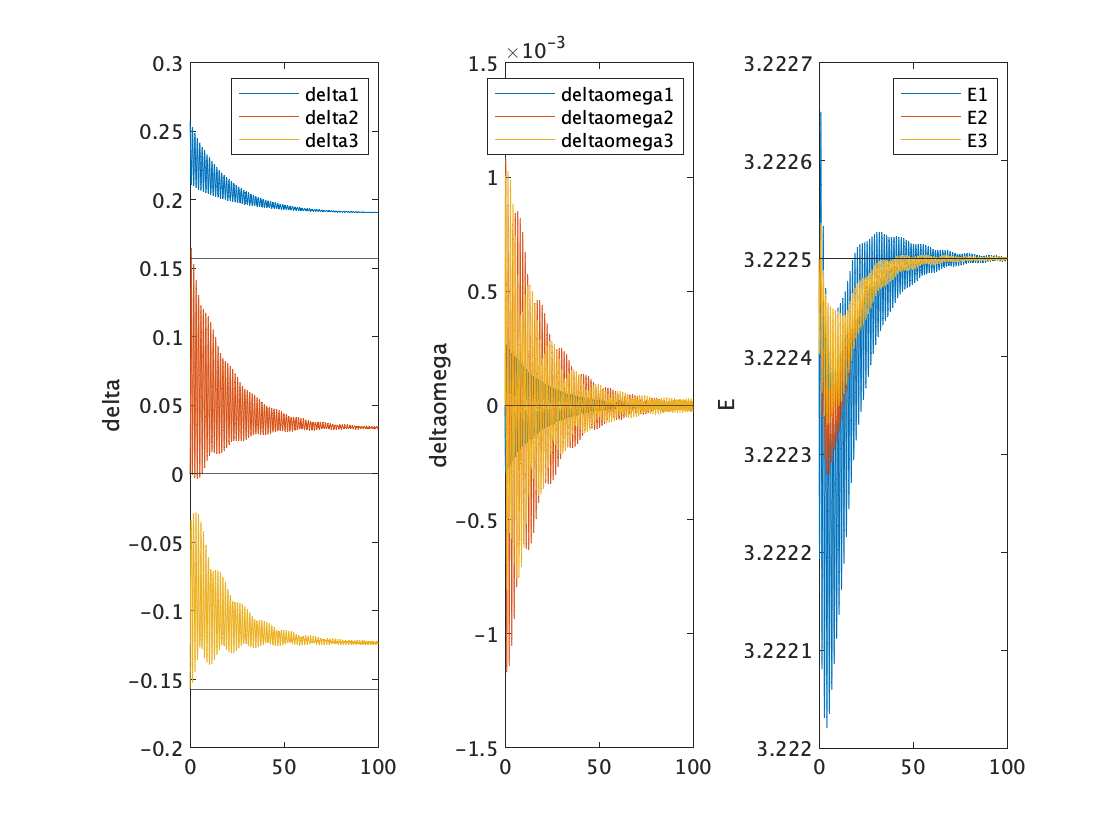

initial_generator_state =     0.2571
         0
   -0.1571
         0
         0
         0
    3.2225
    3.2225
    3.2225


左辺と右辺の要素数が異なるため、代入を実行できません。

エラー: plot_FG_accum_func (行 51)
      nabla(t) = nabla(t) - E(t,i)*sigma_sin*(delta(t,i)-delta_star(i)) + Vfield_star/(Xd(i)-Xq(i))*(E(t,i)-E_star(i));

エラー: plot_generator_state (行 56)
      plot_FG_accum_func(steady_generator_state, delta, deltaomega, E, Bred, Xd, Xq, Vfield_star, omega0, M, t_sol, flag

clear
tspan = [0 100];

%定常値を設定
%{
judge ok!

安定
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];

安定
steady_delta = [-0.2607;0.6415;0.4656];
steady_deltaomega = [0;0;0];
steady_E = [4.3303;3.2225;2.2370];

ぎり安定
steady_delta = [-1.25664;0;0];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

不安定
steady_delta = [0.942478;0;-1.41372];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

めちゃ安定
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
%}

flag_accum = 1;
flag_accum_diff = 1;

steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

error = [0.1;0;0;0;0;0;0;0;0];
plot_generator_state_wrap = @(error) plot_generator_state(error,tspan,steady_generator_state,flag_accum,flag_accum_diff);

figure;
plot_generator_state_wrap(error);

sgtitle(['初期誤差: ',num2str(transpose(error))]);

%figure;
%f = fit(t_U(:,1),t_U(:,2),'poly4');
%syms x f1(x) diff2_f1(x)
%f1(x) = f.p1*x^4 + f.p2*x^3 + f.p3*x^2 + f.p4*x + f.p5;
%diff2_f1(x) = diff(f1,2);
%diff2_f1(1:10)  %任意のxで W(x)>=0 
%F = solve(diff2_f1 == 0, x)  %かつ、これが複素数なら蓄積関数WはRealな解を持たなくて、半正定関数

%plot(f,t_U(:,1),t_U(:,2))
